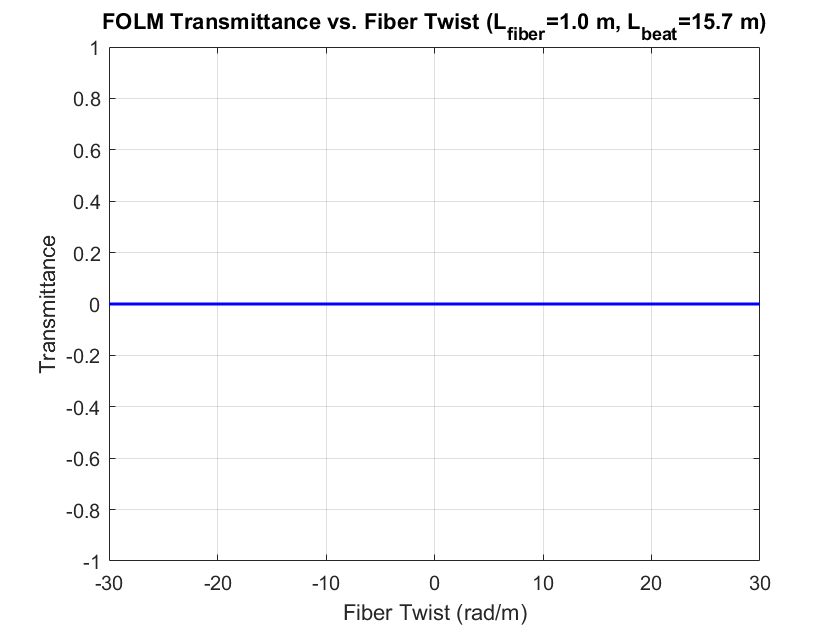

alpha = 0.5;          % Coupler split ratio (0.5 for 50:50)
L_fiber = 1.0;        % Fiber length (m)
L_beat = 15.7;        % Beat length (m)
delta_1 = 2*pi/L_beat;% Linear birefringence parameter
g = 0.16;             % Circular birefringence coefficient
theta_range = linspace(-30, 30, 1000); % Twist range (rad/m)

T = zeros(size(theta_range));
for i = 1:length(theta_range)
    theta = theta_range(i);
    
    % Jones matrix for the twisted fiber segment
    J_fiber = twisted_fiber_jones(theta, delta_1, L_fiber);
    
    % Simplified loop mirror model (assuming symmetric couplers)
    J_loop = J_fiber; % Replace with full component chain if needed
    
    % Output field (Equation 1 from Kuzin2001)
    E_in = [1; 0]; % Input field (x-polarized)
    E_out = (2*alpha - 1)*J_loop(1,1)*E_in(1) + ...
            ((1 - alpha)*J_loop(1,2) + alpha*J_loop(2,1))*E_in(2);
    
    % Transmittance
    T(i) = abs(E_out)^2;
end

figure;
plot(theta_range, T, 'b-', 'LineWidth', 1.5);
xlabel('Fiber Twist (rad/m)');
ylabel('Transmittance');
title('FOLM Transmittance vs. Fiber Twist (L_{fiber}=1.0 m, L_{beat}=15.7 m)');
grid on;

function C = twisted_fiber_jones(theta, delta_1, L)
    delta_c = 0.14 * theta; % Circular birefringence (for silica)
    lambda = sqrt((delta_1/2)^2 + (theta + delta_c/2)^2);
    C = [cos(lambda*L) - 1i*(delta_1/(2*lambda))*sin(lambda*L), ...
         (theta + delta_c/2)/lambda * sin(lambda*L);
         - (theta + delta_c/2)/lambda * sin(lambda*L), ...
         cos(lambda*L) + 1i*(delta_1/(2*lambda))*sin(lambda*L)];
end